%% Longitudinal car-following QP for Gurobi (fixed + defensive checks)
% Paste into a MATLAB Live Script. Requires Gurobi MATLAB interface.
clear; clc;

%% ---------------------------
% Parameters (edit as needed)
% ---------------------------
N = 30;           % horizon steps
dt = 0.2;         % s

% Follower initial state
x0 = 0;           % m
v0 = 15;          % m/s

% Leader trajectory (example: constant-speed leader)
vL = 18 * ones(N+1,1);   % leader speed
xL = zeros(N+1,1);
xL(1) = 20;               % leader starts ahead of ego by 20 m (change as needed)
for k = 2:N+1
    xL(k) = xL(k-1) + vL(k-1)*dt;
end

% Limits
a_min = -3.5; a_max = 2.0;    % m/s^2
v_min = 0;    v_max = 33.33;  % m/s (~120 km/h)
eps_slack = 50;               % big upper bound on slack

% headway params
d0 = 2.0;    % m minimum standstill distance
h  = 1.2;    % s desired time headway

% objective weights
w_d = 200.0;  % weight for distance error
w_e = 1.0;    % weight for control effort (energy surrogate)
w_v = 0.1;    % weight for speed tracking
w_s = 5000.0; % slack penalty (very large)

% reference speed (can be leader speed or desired cruise)
v_ref = vL; % track leader speed

% reasonable position bounds derived from leader trajectory
pos_margin = 200; % meters margin around leader positions (prevent x -> +/-inf)
x_lb_global = min(xL) - pos_margin;
x_ub_global = max(xL) + pos_margin;

%% ---------------------------
% Decision vector indexing
% ---------------------------
na = N; nv = N+1; nx = N+1; ns = N;   % s for k=1..N -> ns = N
nz = na + nv + nx + ns;

a_idx = (1:na)';
v_idx = (na+1 : na+nv)';
x_idx = (na+nv+1 : na+nv+nx)';
s_idx = (na+nv+nx+1 : na+nv+nx+ns)';

%% ---------------------------
% Build quadratic objective (Hessian) and linear term (f)
% Objective: 0.5*z'*H*z + f'*z
% ---------------------------
H = sparse(nz,nz);
f = zeros(nz,1);

% (1) control effort: w_e * sum a_k^2 -> Hessian diag = 2*w_e
H(sub2ind([nz nz], a_idx, a_idx)) = 2*w_e;

% (2) speed tracking: w_v*(v_k - v_ref_k)^2 = w_v*v_k^2 - 2*w_v*v_ref_k*v_k + const
H(sub2ind([nz nz], v_idx, v_idx)) = H(sub2ind([nz nz], v_idx, v_idx)) + 2*w_v;
f(v_idx) = f(v_idx) + (-2*w_v .* v_ref(:));

% (3) distance error: w_d*( xL_k - x_k - d0 - h*v_k )^2 for k = 1..N
% Expand and add quadratic and linear terms safely
for k = 1:N
    xi = x_idx(k+1);  % x_k
    vi = v_idx(k+1);  % v_k
    rhs_const = (xL(k+1) - d0);
    % quadratic contributions:
    H(xi, xi) = H(xi, xi) + 2*w_d;
    H(vi, vi) = H(vi, vi) + 2*w_d*(h^2);
    % cross term: symmetric entries
    H(xi, vi) = H(xi, vi) + 2*w_d*(h);
    H(vi, xi) = H(xi, vi);
    % linear contributions
    f(xi) = f(xi) + 2*w_d * (-rhs_const);
    f(vi) = f(vi) + 2*w_d * (-h * rhs_const);
end

% (4) slack penalty: w_s * s_k^2
H(sub2ind([nz nz], s_idx, s_idx)) = H(sub2ind([nz nz], s_idx, s_idx)) + 2*w_s;

% Small regularization to improve numerical definiteness
reg = 1e-8;
H = H + reg * speye(nz);

% ensure symmetry
H = (H + H')/2;

%% ---------------------------
% Equality constraints (dynamics)
% v_{k+1} - v_k - a_k*dt = 0  for k=0..N-1
% x_{k+1} - x_k - v_k*dt - 0.5*a_k*dt^2 = 0  for k=0..N-1
% initial cond: v_0 = v0, x_0 = x0
% ---------------------------
Aeq = sparse(2*N + 2, nz);
beq = zeros(2*N + 2,1);
row = 1;

% v dynamics
for k = 0:N-1
    ai = a_idx(k+1);
    vi = v_idx(k+1);
    vip1 = v_idx(k+2);
    Aeq(row, vip1) = 1;
    Aeq(row, vi)   = -1;
    Aeq(row, ai)   = -dt;
    beq(row) = 0;
    row = row + 1;
end

% x dynamics
for k = 0:N-1
    ai = a_idx(k+1);
    xi = x_idx(k+1);
    xip1 = x_idx(k+2);
    vi = v_idx(k+1);
    Aeq(row, xip1) = 1;
    Aeq(row, xi)   = -1;
    Aeq(row, vi)   = -dt;
    Aeq(row, ai)   = -0.5 * dt^2;
    beq(row) = 0;
    row = row + 1;
end

% initial conditions
Aeq(row, v_idx(1)) = 1; beq(row) = v0; row = row + 1;
Aeq(row, x_idx(1)) = 1; beq(row) = x0; row = row + 1;

%% ---------------------------
% Inequality constraints (safety)
% For k=1..N: -x_k + h v_k + s_k <= xL_k - d0
% ---------------------------
A = sparse(N, nz);
b = zeros(N,1);
for k = 1:N
    xi = x_idx(k+1);
    vi = v_idx(k+1);
    si = s_idx(k);
    A(k, xi) = -1;
    A(k, vi) = h;
    A(k, si) = 1;
    b(k) = xL(k+1) - d0;
end

%% ---------------------------
% Bounds
% ---------------------------
lb = -inf(nz,1);
ub =  inf(nz,1);

% a bounds
lb(a_idx) = a_min;
ub(a_idx) = a_max;

% v bounds
lb(v_idx) = v_min;
ub(v_idx) = v_max;

% s bounds
lb(s_idx) = 0;
ub(s_idx) = eps_slack;

% x bounds (added to avoid unbounded positions)
lb(x_idx) = x_lb_global;
ub(x_idx) = x_ub_global;

%% ---------------------------
% Defensive checks before solve
% ---------------------------
% 1) Dimensions
assert(size(H,1) == nz && size(H,2) == nz, 'Hessian size mismatch.');
assert(numel(f) == nz, 'Linear objective size mismatch.');
assert(size(Aeq,2) == nz, 'Aeq column mismatch.');
assert(size(A,2) == nz, 'A column mismatch.');

% 2) No zero rows in constraints (will indicate missing constraints)
zeroRowsA = find(all(A==0,2));
zeroRowsAeq = find(all(Aeq==0,2));
if ~isempty(zeroRowsA)
    warning('Found %d all-zero rows in A (inequalities). Rows: %s', numel(zeroRowsA), mat2str(zeroRowsA'));
end
if ~isempty(zeroRowsAeq)
    warning('Found %d all-zero rows in Aeq (equalities). Rows: %s', numel(zeroRowsAeq), mat2str(zeroRowsAeq'));
end

% 3) Make sure lb <= ub
if any(lb > ub)
    idx = find(lb > ub,1);
    error('Found lb > ub at index %d (lb=%g, ub=%g).', idx, lb(idx), ub(idx));
end

%% ---------------------------
% Build Gurobi model and solve
% ---------------------------
model.Q = sparse(H);      % Gurobi interprets objective as 0.5*x'Q*x + obj'*x
model.obj = f;            % linear term
model.A = sparse([A; Aeq]);
model.rhs = [b; beq];

% sense: first part inequalities '<', then equalities '='
sense = [repmat('<', size(A,1),1); repmat('=', size(Aeq,1),1)];
model.sense = sense;

model.lb = lb;
model.ub = ub;

% Gurobi parameters: show more info if infeasible/unbounded
params.outputflag = 1;
params.InfUnbdInfo = 1;
params.NumericFocus = 3;  % be more robust numerically (slower, but safer)

% Solve
result = gurobi(model, params);

Set parameter Username
Set parameter LicenseID to value 2719585
Set parameter InfUnbdInfo to value 1
Set parameter NumericFocus to value 3
Academic license - for non-commercial use only - expires 2026-10-08
Gurobi Optimizer version 12.0.3 build v12.0.3rc0 (win64 - Windows 11.0 (26100.2))

CPU model: Intel(R) Core(TM) i7-14700HX, instruction set [SSE2|AVX|AVX2]
Thread count: 20 physical cores, 28 logical processors, using up to 28 threads

Non-default parameters:
InfUnbdInfo  1
LogToConsole  0
NumericFocus  3

Optimize a model with 92 rows, 122 columns and 302 nonzeros
Model fingerprint: 0xc36a189d
Model has 152 quadratic objective terms
Coefficient statistics:
  Matrix range     [2e-02, 1e+00]
  Objective range  [4e+00, 6e+04]
  QObjective range [2e-08, 2e+04]
  Bounds range     [2e+00, 3e+02]
  RHS range        [2e+01, 1e+02]
Presolve removed 32 rows and 32 columns
Presolve time: 0.02s
Presolved: 60 rows, 90 columns, 


% Interpret result
if isfield(result,'status')
    switch result.status
        case 'OPTIMAL'
            zopt = result.x;
            a_opt = zopt(a_idx);
            v_opt = zopt(v_idx);
            x_opt = zopt(x_idx);
            s_opt = zopt(s_idx);
            fprintf('Gurobi status: %s. Objective: %g\n', result.status, result.objval);
        case 'INF_OR_UNBD'
            error(['Gurobi returned INF_OR_UNBD. '...
                'Possible causes: missing bounds or constraints, or model numerically ill-conditioned. '...
                'Check the earlier warnings and try tightening bounds on position/velocity or regularize H.']);
        otherwise
            error('Gurobi returned status: %s', result.status);
    end
else
    error('Gurobi did not return a result structure.');
end

Gurobi status: OPTIMAL. Objective: -1.89573e+07


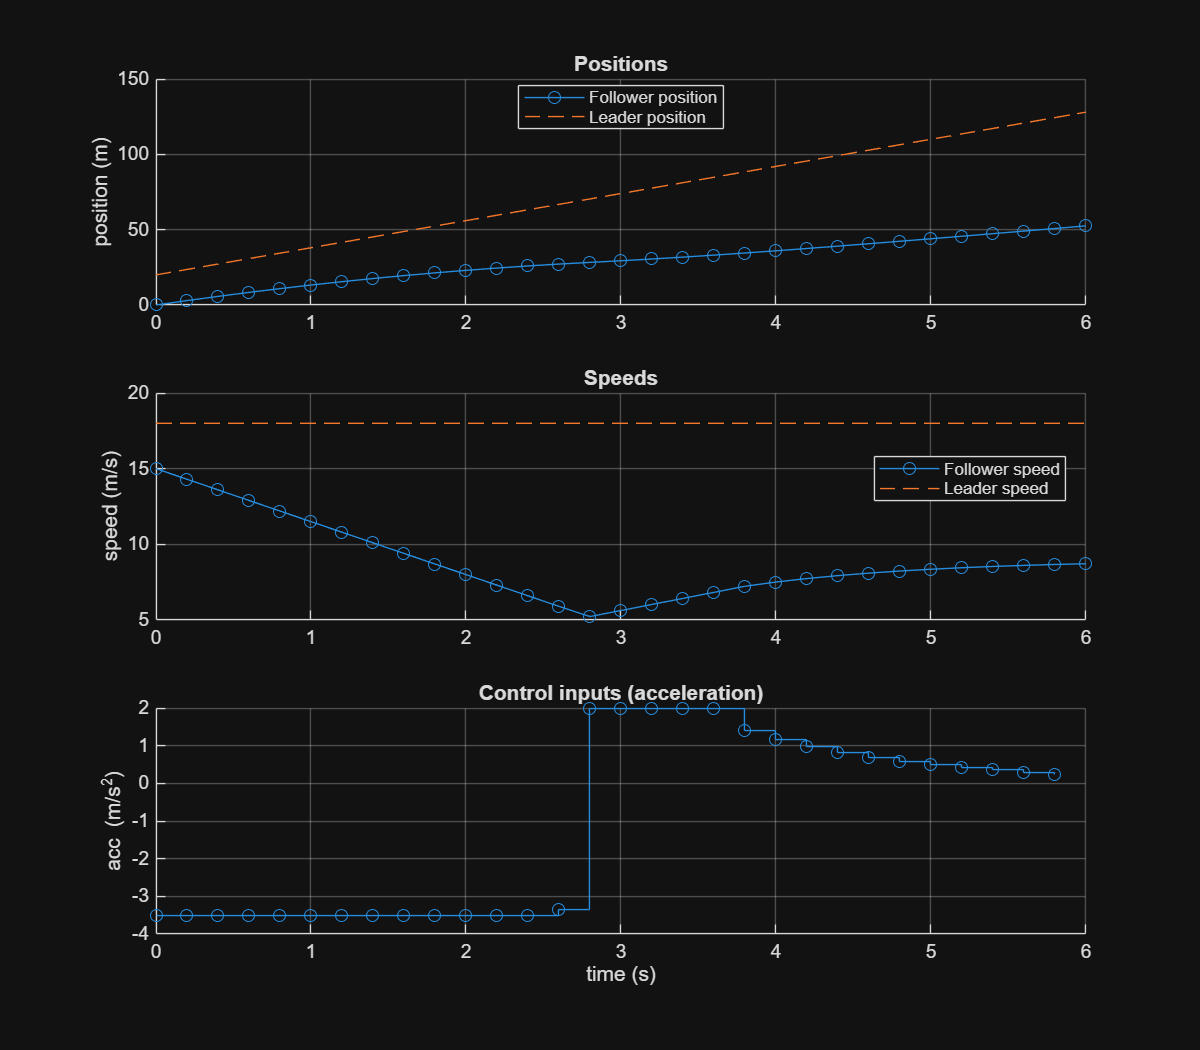


%% ---------------------------
% Plot results
% ---------------------------
tvec = 0:dt:N*dt;

figure('Name','Car-Following QP Results','NumberTitle','off','Position',[100 100 800 700]);
subplot(3,1,1); hold on; grid on;
plot(tvec, x_opt, '-o','DisplayName','Follower position');
plot(tvec, xL, '--','DisplayName','Leader position');
ylabel('position (m)');
legend('Location','best');
title('Positions');

subplot(3,1,2); hold on; grid on;
plot(tvec, v_opt, '-o','DisplayName','Follower speed');
plot(tvec, vL, '--','DisplayName','Leader speed');
ylabel('speed (m/s)');
legend('Location','best');
title('Speeds');

subplot(3,1,3); hold on; grid on;
stairs(0:dt:(N-1)*dt, a_opt, '-o','DisplayName','Acceleration');
ylabel('acc (m/s^2)');
xlabel('time (s)');
title('Control inputs (acceleration)');

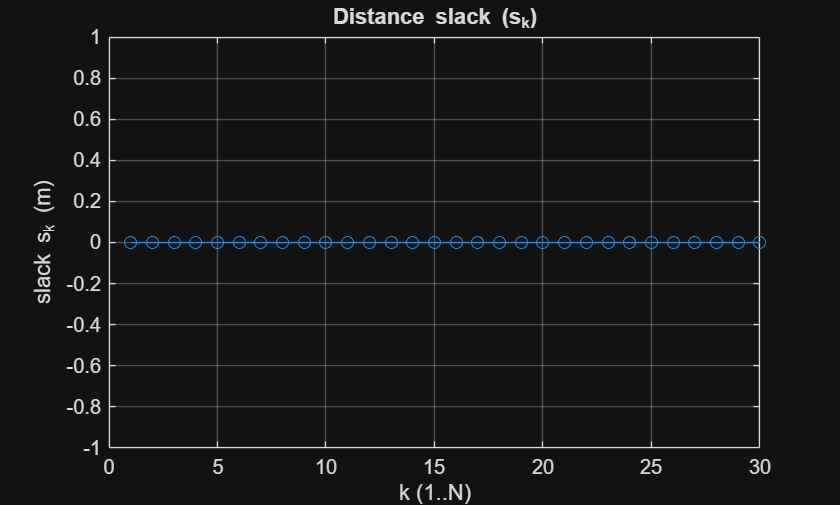


figure('Name','Slack','NumberTitle','off');
plot(1:N, s_opt, '-o');
xlabel('k (1..N)');
ylabel('slack s_k (m)');
title('Distance slack (s_k)');
grid on;